## Naloga 1. Zveza med Bernsteinovo in potenčno bazo.

% polinom v potenčni bazi
p = [4 7 2 8 9 1 4];

b = power2bernstein(p)

b =     4.0000    4.1667    4.9333    6.7000   10.0000   16.6667   35.0000


bernstein2power(b)

ans =     4.0000    7.0000    2.0000    8.0000    9.0000    1.0000    4.0000


power2bernstein(1)

ans = 1

power2bernstein([0 1])

ans =      1     1


power2bernstein([0 0 1])

ans =      1     1     1


power2bernstein([1 0])

ans =      0     1


power2bernstein([0 1 0])

ans =          0    0.5000    1.0000


power2bernstein([0 0 1 0])

ans =          0    0.3333    0.6667    1.0000


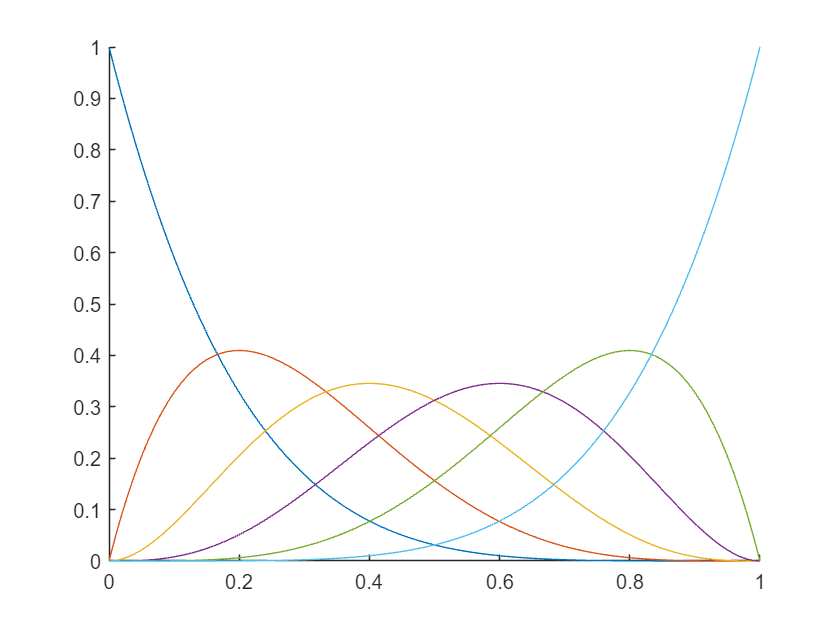

n = 5;
x = linspace(0,1);
clf
hold on
for i = 0:n
    b = zeros(1,n+1);
    b(i+1) = 1;
    plot(x,polyval(bernstein2power(b),x));
end
hold off

## Naloga 2. De Casteljaujev postopek

B = [0 0; 1 2; 3 3; 4 -1; 0 2];
t = linspace(0,1,100);
P = bezier(B,t)

P =          0         0
    0.0410    0.0802
    0.0832    0.1590
    0.1265    0.2365
    0.1709    0.3124
    0.2163    0.3868
    0.2627    0.4595
    0.3099    0.5304
    0.3581    0.5995
    0.4071    0.6668


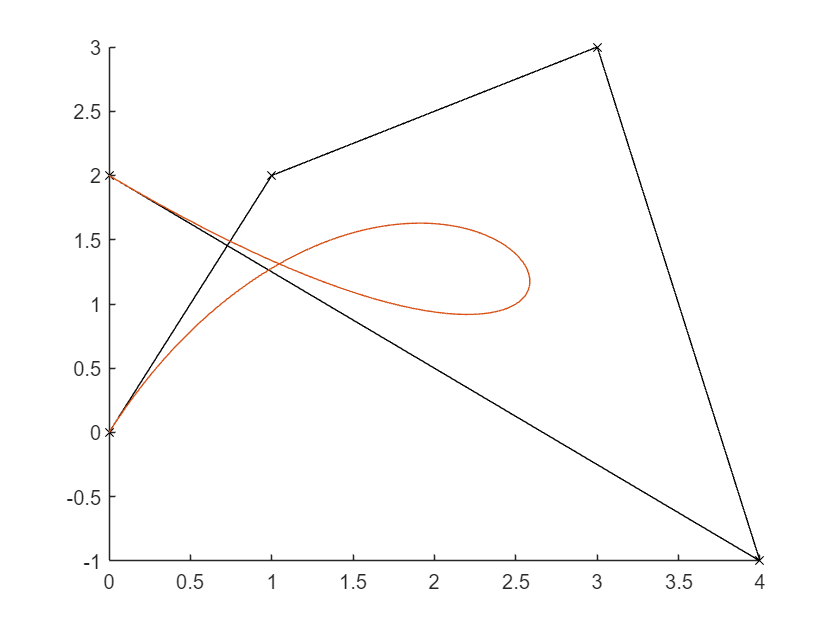

clf
hold on
plot(B(:,1),B(:,2), "Marker","x","Color","black")
plot(P(:,1),P(:,2))
hold off

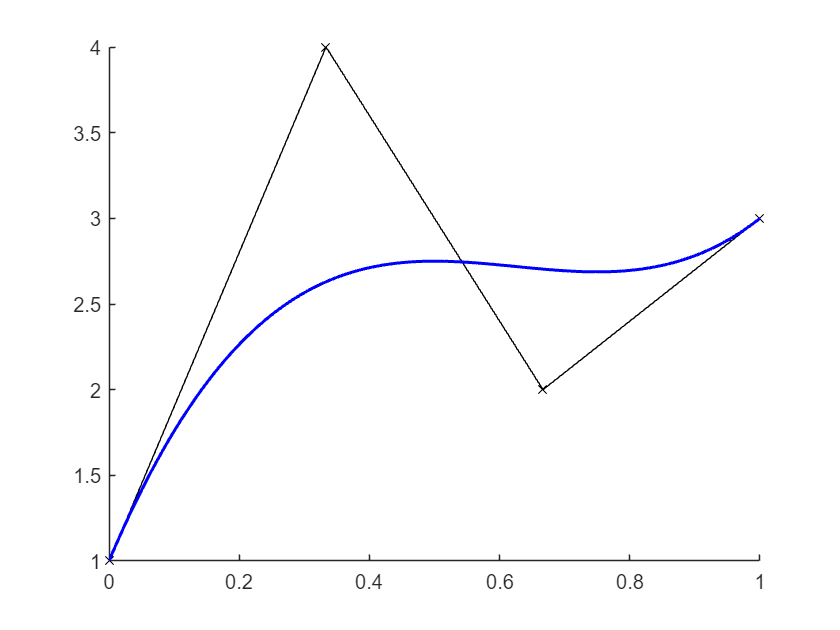

ans =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 1.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.0101 0.0202 0.0303 0.0404 0.0505 0.0606 0.0707 0.0808 0.0909 0.1010 0.1111 0.1212 0.1313 0.1414 0.1515 0.1616 0.1717 0.1818 0.1919 0.2020 0.2121 0.2222 0.2323 0.2424 0.2525 0.2626 0.2727 0.2828 0.2929 0.3030 … ] (1×100 double)
              YData: [1 1.0894 1.1758 1.2592 1.3397 1.4173 1.4921 1.5642 1.6335 1.7002 1.7643 1.8258 1.8848 1.9413 1.9954 2.0471 2.0965 2.1437 2.1886 2.2313 2.2720 2.3105 2.3471 2.3816 2.4143 2.4450 2.4740 2.5011 2.5266 2.5503 2.5725 … ] (1×100 double)

  Show all propert

clf
B = [1; 4; 2; 3];
plotbezier(B,t,"b")

clf
B = [1,0,3; 4,-4,0; 2,3,0; 0,0,5];
plotbezier(B,t,"b")

ans =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 1.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 1.0894 1.1757 1.2591 1.3395 1.4169 1.4915 1.5631 1.6320 1.6980 1.7612 1.8217 1.8794 1.9345 1.9869 2.0367 2.0839 2.1285 2.1705 2.2101 2.2472 2.2819 2.3141 2.3440 2.3715 2.3967 2.4196 2.4403 2.4587 2.4749 2.4890 … ] (1×100 double)
              YData: [0 -0.1179 -0.2291 -0.3339 -0.4324 -0.5246 -0.6107 -0.6909 -0.7653 -0.8340 -0.8971 -0.9547 -1.0071 -1.0543 -1.0964 -1.1337 -1.1661 -1.1939 -1.2171 -1.2360 -1.2506 -1.2610 -1.2675 -1.2701 -1.2689 -1.2641 -1.2558 … ] (1×100 double)
              ZData: [3 2.9100 2.8219 2.7356 2.6512 2.5687 2.4880 2.4093 2.3326 2.2577 2.1848 2.1139 2.0449 1.9779 1.9129 1.8499 1.7890 1.7301 1.6732 1.6184 1.5656 1.5150 1.4664 1.4199 1.3756 1.3334 1.2933 1.255

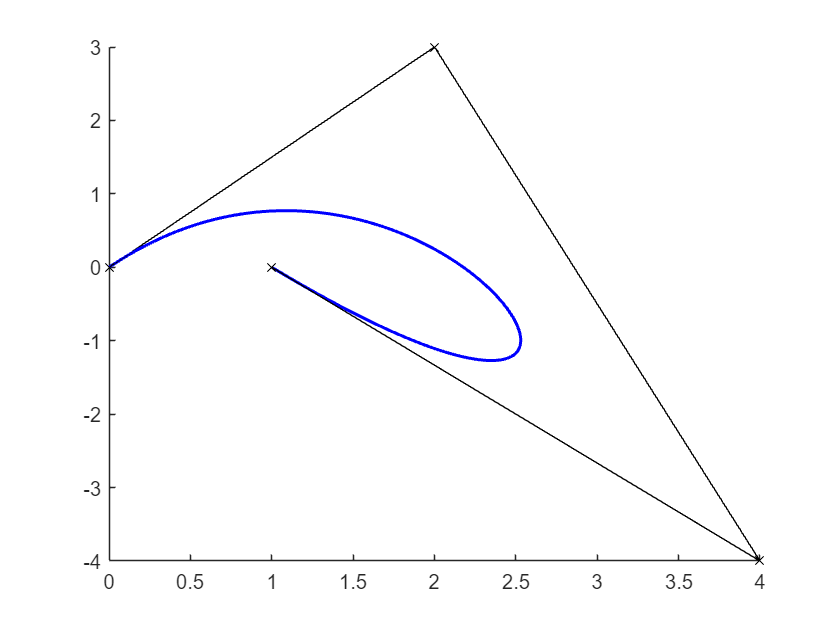

hold off

## Naloga 3. Odvodi Bezierjeve krivulje

t = (0.46:0.01:0.54)';
B = [
    -2/3, -4/5;
    1/3,  1/5;
    0,    0;
    -1/3, 1/5;
    2/3,  -4/5
];
d1b = bezierder(B,1,t);
tab = table();
tab{:,'t'} = t;
tab{:,'x'} = d1b(:,1);
tab{:,'y'} = d1b(:,2);
tab

tab = 9×3 table
     t        x           y    
    ____    ______    _________

    0.46    0.0256      0.19282
    0.47    0.0144      0.14435
    0.48    0.0064     0.096102
    0.49    0.0016     0.048013
     0.5         0            0
    0.51    0.0016    -0.048013
    0.52    0.0064    -0.096102
    0.53    0.0144     -0.14435
    0.54    0.0256     -0.19282


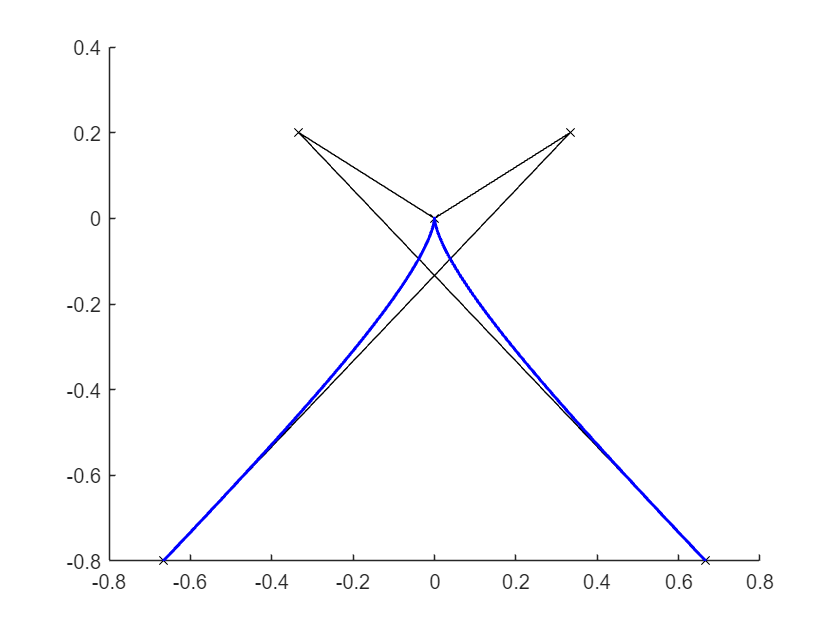

t = linspace(0,1);
[d1b,d1B] = bezierder(B,1,t);
[d2b,d2B] = bezierder(B,2,t);
clf
plotbezier(B,t,"blue");

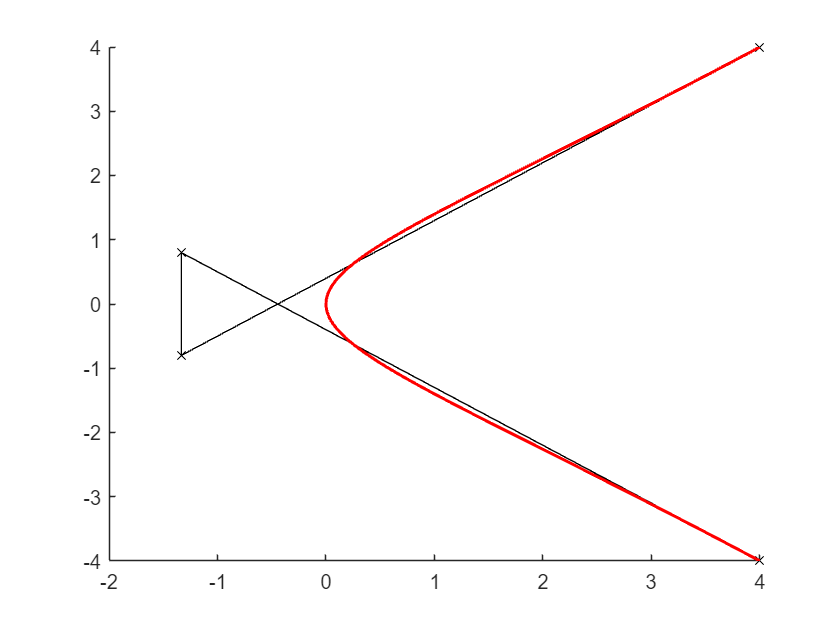

clf
plotbezier(d1B,t, "red");

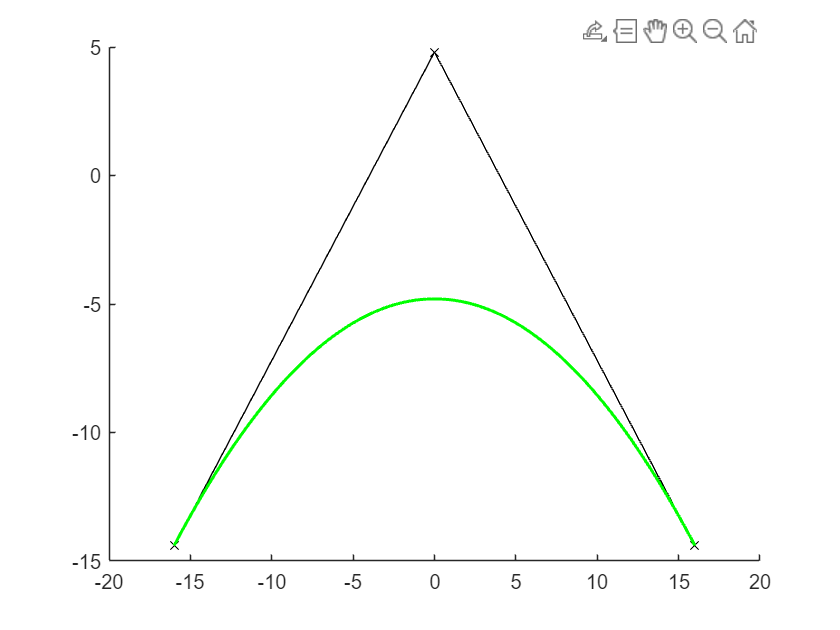

clf
plotbezier(d2B,t, "green");

## Naloga 4. Opisi krožnice z Bezierjevimi krivuljami

n = 5;
fi = pi/n;

B1 = bezierarc(fi,1)

B1 =     0.8090   -0.5878
    1.2361         0
    0.8090    0.5878


B2 = bezierarc(fi,2)

B2 =     0.8090   -0.5878
    1.0049   -0.3181
    1.0049    0.3181
    0.8090    0.5878


B3 = bezierarc(fi,3)

B3 =     0.8090   -0.5878
    1.0637   -0.2373
    1.0637    0.2373
    0.8090    0.5878


% izračun točk na Bezierjevih krivuljah
t = linspace(0,1,1001);
b1 = bezier(B1,t);
b2 = bezier(B2,t);
b3 = bezier(B3,t);

% radialne napake
[e1,e2,e3] = deal(0);
for i = 1:length(t)
e1 = max(e1,abs(1-norm(b1(i,:))));
e2 = max(e2,abs(1-norm(b2(i,:))));
e3 = max(e3,abs(1-norm(b3(i,:))));
end
[e1,e2,e3]

ans =     0.0225    0.0440    0.0001


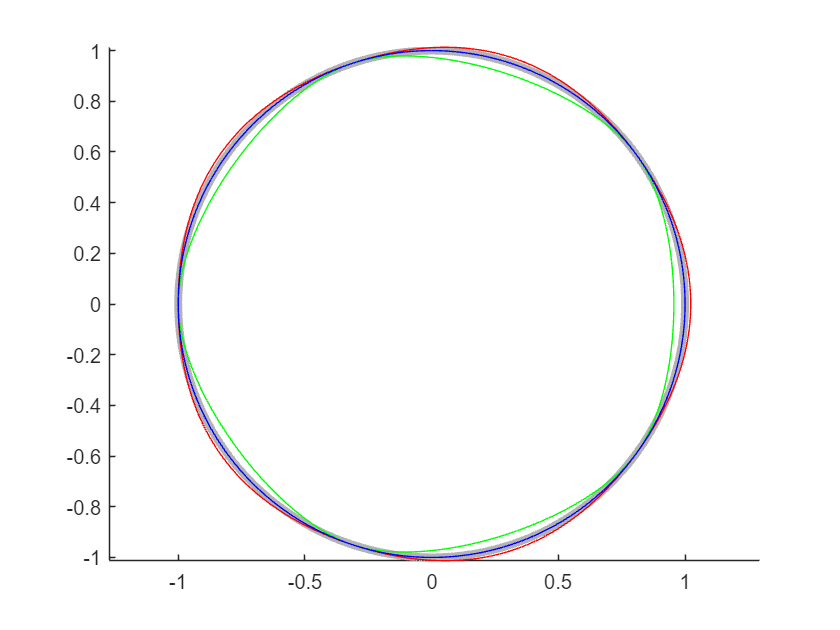


% rotacijska matrika
c = cos(2*fi);
s = sin(2*fi);
R = [c -s; s c];

clf
hold on
plot(cos(2*pi*t),sin(2*pi*t),'Color',0.7*[1 1 1],'LineWidth',4);
plot(b1(:,1),b1(:,2),'r');
plot(b2(:,1),b2(:,2),'g');
plot(b3(:,1),b3(:,2),'b');
for i = 1:n-1
    B1 = (R*B1')';
    B2 = (R*B2')';
    B3 = (R*B3')';
    b1 = bezier(B1,t);
    b2 = bezier(B2,t);
    b3 = bezier(B3,t);
    plot(b1(:,1),b1(:,2),'r');
    plot(b2(:,1),b2(:,2),'g');
    plot(b3(:,1),b3(:,2),'b');
end
hold off
axis equal

## Naloga 5. Subdivizija Bezierjeve krivulje

B = [0 0; 2 3; 4 2; 5 -1];
BS = beziersub(B,0.5,1);
[BS{1} BS{2}]

ans =          0         0    2.8750    1.7500
    1.0000    1.5000    3.7500    1.5000
    2.0000    2.0000    4.5000    0.5000
    2.8750    1.7500    5.0000   -1.0000


BS2 = beziersub(B,0.5,2);
[BS2{1} BS2{2}; BS2{3} BS2{4}]

ans =          0         0    1.4844    1.5312
    0.5000    0.7500    1.9688    1.8125
    1.0000    1.2500    2.4375    1.8750
    1.4844    1.5312    2.8750    1.7500
    2.8750    1.7500    4.0781    0.8438
    3.3125    1.6250    4.4375    0.3750
    3.7188    1.3125    4.7500   -0.2500
    4.0781    0.8438    5.0000   -1.0000


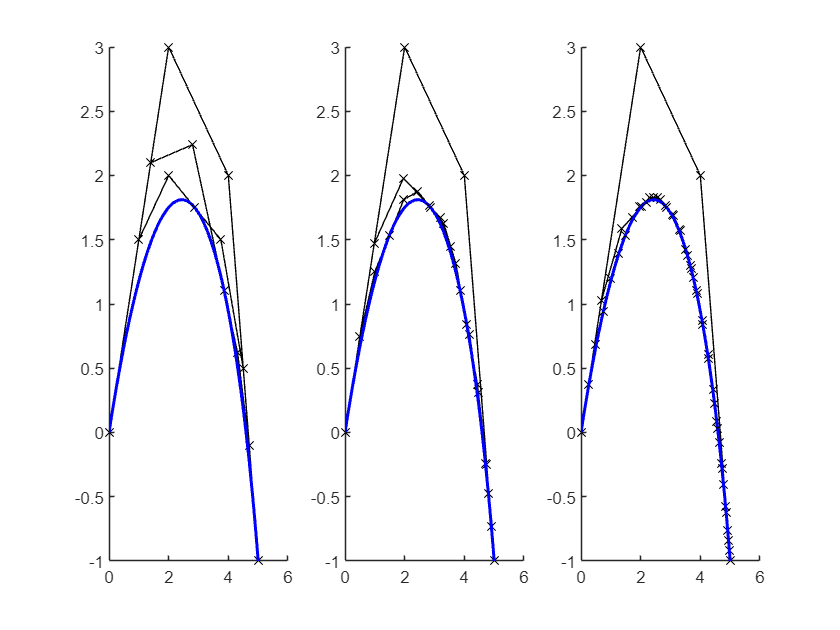

t = linspace(0,1);
subt = 0.5;
for k = 1:3
    subplot(1,3,k);
    plotbezier(B,t, "b");
    BS = beziersub(B,subt,k);
    for d = 1:length(BS)
        plotbezier(BS{d},t, "b");
    end
end

## Naloga 6. Višanje stopnje Bezierjeve krivulje

B = [0 0; 2 6; 3 0; 5 4; 7 1; 5 5; 10 6];
bezierelv(B, 2)

ans =          0         0
    1.5000    4.5000
    2.4643    2.5714
    3.6071    2.0714
    5.0000    2.5000
    6.0714    2.5000
    6.2500    2.8929
    6.2500    5.2500
   10.0000    6.0000


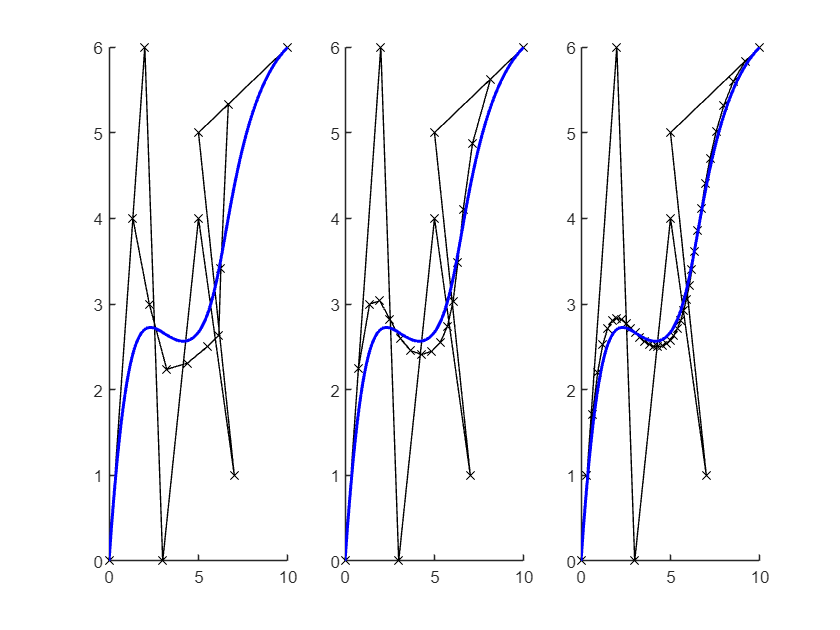

t = linspace(0,1);
k = [3 10 30];
clf
hold on
for j = 1:3
    Br = bezierelv(B,k(j));
    subplot(1,3,j);
    plotbezier(B,t, "b");
    plotbezier(Br,t, "b");
end
hold off

## Naloga 7. Parametrizacija sestavljene krivulje

P = [-5 0; -2 -1; 0 3; 3 0; 7 -1];
ue = alphaparam(P,0)

ue =      0     1     2     3     4


uc = alphaparam(P,0.5)

uc =                    0   1.778279410038923   3.893021936920051   5.952789080827168   7.983332265696099


ut = alphaparam(P,1)

ut =                    0   3.162277660168380   7.634413615167960  11.877054302287245  16.000159927904907


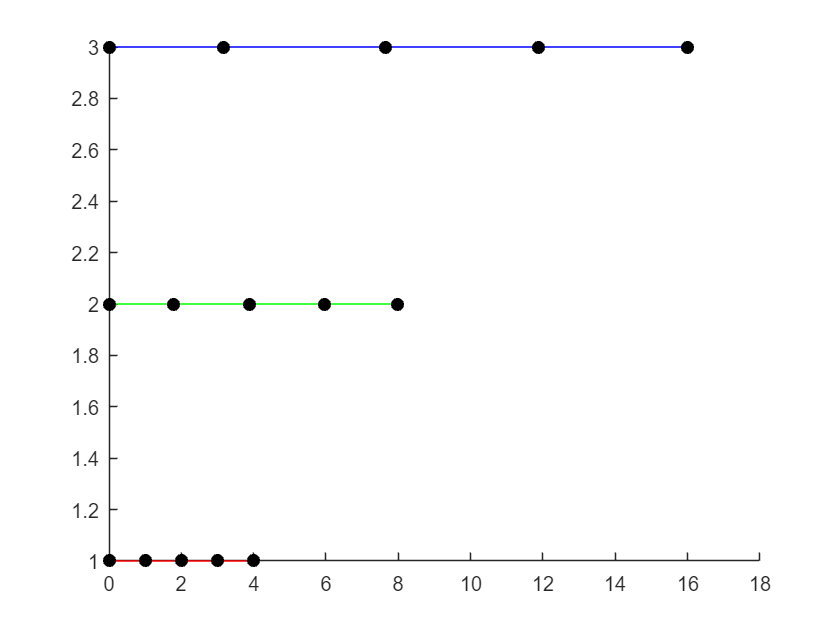

z = ones(1,5);
clf
hold on
plot(ue,z*1,'ro-','MarkerEdgeColor','k','MarkerFaceColor','k');
plot(uc,z*2,'go-','MarkerEdgeColor','k','MarkerFaceColor','k');
plot(ut,z*3,'bo-','MarkerEdgeColor','k','MarkerFaceColor','k');
hold off

## Naloga 8. Kubični C2 zlepek

D = [-5 0; -4 1; -2 -1; 0 3; 3 0; 5 2; 7 -1];
P = D([1 3 4 5 7],:);
ue = alphaparam(P,0);
Be = beziercubspline(ue,D);
[Be{1} Be{2}]

ans =   -5.000000000000000                   0  -2.166666666666667   0.166666666666667
  -4.000000000000000   1.000000000000000  -1.333333333333333   0.333333333333333
  -3.000000000000000                   0  -0.666666666666667   1.666666666666667
  -2.166666666666667   0.166666666666667   0.166666666666667   1.833333333333333


[Be{3} Be{4}]

ans =    0.166666666666667   1.833333333333333   3.000000000000000   1.000000000000000
   1.000000000000000   2.000000000000000   4.000000000000000   1.000000000000000
   2.000000000000000   1.000000000000000   5.000000000000000   2.000000000000000
   3.000000000000000   1.000000000000000   7.000000000000000  -1.000000000000000


uc = alphaparam(P,0.5);
Bc = beziercubspline(uc,D);
[Bc{1} Bc{2}; Bc{3} Bc{4}]

ans =   -5.000000000000000                   0  -2.317250055967985   0.135986089335964
  -4.000000000000000   1.000000000000000  -1.402539083480572   0.194921833038857
  -3.086427233725890   0.086427233725890  -0.692034310619621   1.615931378760759
  -2.317250055967985   0.135986089335964   0.176486618325005   1.799132330090401
   0.176486618325005   1.799132330090401   3.019816835853540   0.994523570913139
   1.022429256965849   1.977570743034151   4.007144680156073   1.007144680156073
   2.018279183705418   0.981720816294582   5.000000000000000   2.000000000000000
   3.019816835853540   0.994523570913139   7.000000000000000  -1.000000000000000


ut = alphaparam(P,1);
Bt = beziercubspline(ut,D);
[Bt{1} Bt{2}; Bt{3} Bt{4}]

ans =   -5.000000000000000                   0  -2.465721945384101   0.127430612277517
  -4.000000000000000   1.000000000000000  -1.467497987348698   0.065004025302603
  -3.171572875253810   0.171572875253810  -0.714426419066258   1.571147161867484
  -2.465721945384101   0.127430612277517   0.188486005965480   1.768094965197602
   0.188486005965480   1.768094965197602   3.039523596748690   0.989257830081507
   1.045063943195377   1.954936056804623   4.014288630928197   1.014288630928197
   2.036498651499642   0.963501348500359   5.000000000000000   2.000000000000000
   3.039523596748690   0.989257830081507   7.000000000000000  -1.000000000000000


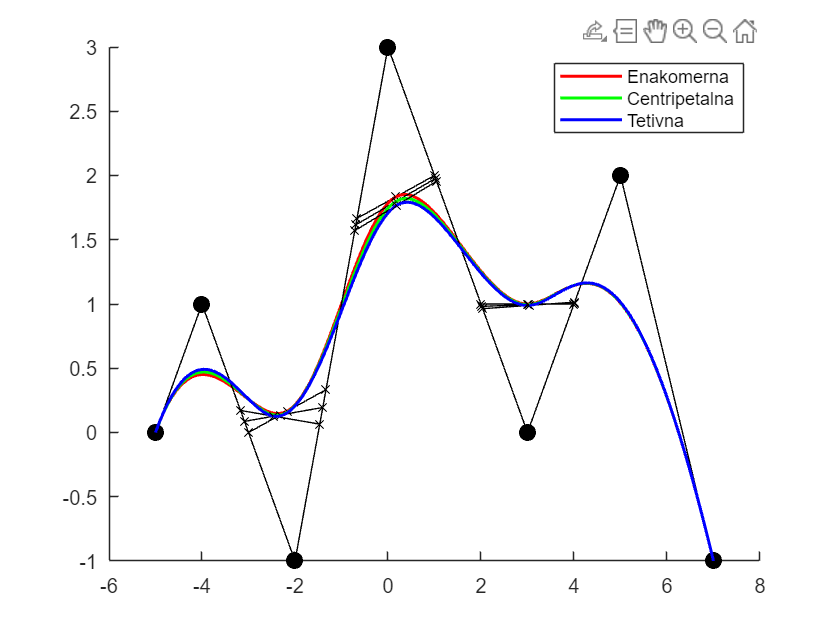

t = linspace(0,1);
clf
hold on
plot(D(:,1),D(:,2),'ko-','MarkerFaceColor','k','MarkerSize',8);
for i = 1:4
s1 = plotbezier(Be{i},t,'r');
s2 = plotbezier(Bc{i},t,'g');
s3 = plotbezier(Bt{i},t,'b');
end
legend([s1 s2 s3], 'Enakomerna', 'Centripetalna', 'Tetivna');
hold off